% Jep Brinkmann Thesis HMM example
clc; close all;

Initiate the HMM

k = number of states

d = number of possible observational values

T = transition matrix

O = emission matrix

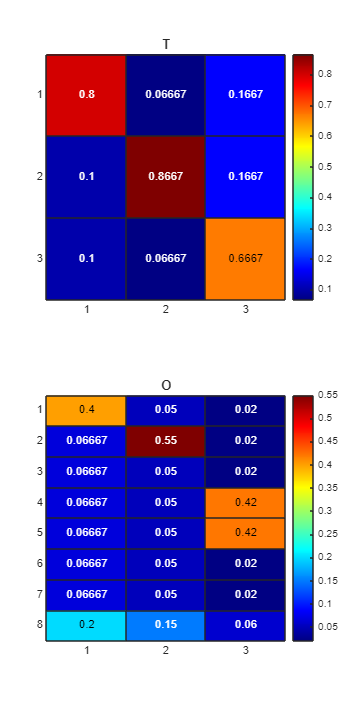

k = 3;
d = 8;

lam = 5;

T = lam * eye(k) + abs(randn(k, k));
T = diag(sum(T, 1)) \ T ;

T = Stochasticize(T);


O = initialize_emission_matrix(d, k, 1);


% O = zeros(d, k);
% 
% for i = 1:k
%     O(:, i) = binopdf(1:d, d, 0.5 * rand + 0.25);
% end
% O = Stochasticize(O);


if(rank(T) ~= k || rank(O) ~= k)
error("Insuffucient rank: Rank of T: " + rank(T) + " - and Rank of O: " + rank(O) + " - must be at least: " + k);
end



% k = 3;
% d = 8;
% 
% lam = 0;
% 
% T = lam * eye(k) + rand(k, k);
% T = T' * T;
% T = Stochasticize(T);
% 
% O = rand(d, k);
% O = Stochasticize(O);
% 
% if(rank(T) ~= k || rank(O) ~= k)
% error("Insuffucient rank: Rank of T: " + rank(T) + " - and Rank of O: " + rank(O) + " - must be at least: " + k);
% end

% k = 3;
% d = 10;
% 
% T = [8/10, 1/15, 1/6; 
%     1/10, 13/15, 1/6; 
%     1/10, 1/15, 2/3];
% 
% O = [6/15, 1/20, 1/50;
%     1/15, 11/20, 1/50;
%     1/15, 1/20, 1/50;
%     1/15, 1/20, 21/50;
%     1/15, 1/20, 21/50;
%     1/15, 1/20, 1/50;
%     1/15, 1/20, 1/50;
%     1/15, 1/20, 1/50;
%     1/15, 1/20, 1/50;
%     1/15, 1/20, 1/50;];

k = 3;
d = 8;

T = [8/10, 1/15, 1/6; 
    1/10, 13/15, 1/6; 
    1/10, 1/15, 2/3];

O = [6/15, 1/20, 1/50;
    1/15, 11/20, 1/50;
    1/15, 1/20, 1/50;
    1/15, 1/20, 21/50;
    1/15, 1/20, 21/50;
    1/15, 1/20, 1/50;
    1/15, 1/20, 1/50;
    3/15, 3/20, 3/50;];

figure('Renderer', 'painters', 'Position', [10 10 600 1200])

subplot(2, 1, 1);
h = heatmap(T, Colormap=jet());
h.Title = 'T';

subplot(2, 1, 2);
h = heatmap(O, Colormap=jet());
h.Title = 'O';

Generate an observational sequence based on the defined HMM3, 4

T_seq = 1e6;

[seq,states] = hmmgenerate(T_seq,T',O');

D = {};
D{1} = (O * T');
D{2} = O;
D{3} = (O * T);

P3 = cpdgen(D)/2;

tic
M = ProbabilityTensorGenerate(seq, 3, d);
toc

Elapsed time is 4.776563 seconds.


norm(P3-M, "fro")

ans = 0.0436


Urand = {};
Urand{1} = rand(d, k);
Urand{2} = rand(d, k);
Urand{3} = rand(d, k);

U = D;
Ten = M;

U_hat = cpd(Ten, k);
U_hat_nls = cpd_nls(Ten, U);
U_hat_minf = cpd_minf(Ten, U);
U_hat_als = cpd_als(Ten, U);
U_hat_rbs = cpd_rbs(Ten, U);
U_hat_gevd = cpd_gevd(ful(Ten), k);
U_hat_sd = cpd3_sd(Ten, U);
U_hat_sgsd = cpd3_sgsd(Ten, U);

Us = [U_hat, U_hat_nls, U_hat_minf, U_hat_als, U_hat_rbs, U_hat_gevd, U_hat_sd, U_hat_sgsd];

for i = 1:3:length(Us)

    B1 = Stochasticize(Us{i});
    B2 = Stochasticize(Us{i+1});
    B3 = Stochasticize(Us{i+2});

    Pbest = PermutationFitEmission(O, B2);
    
    B1 = B1 * Pbest';
    B2 = B2 * Pbest';
    B3 = B3 * Pbest';

    T_hat = pinv(B2) * B3;
    
    Onorm = norm(O - B2, "fro")
    Tnorm = norm(T - T_hat, "fro")
    error = Onorm + Tnorm
    display(" ")

end

Onorm = 0.0061

Tnorm = 0.0103

error = 0.0164

    " "



Onorm = 0.0061

Tnorm = 0.0103

error = 0.0164

    " "



Onorm = 0.0061

Tnorm = 0.0103

error = 0.0164

    " "



Onorm = 0.0058

Tnorm = 0.0104

error = 0.0162

    " "



Onorm = 0.0059

Tnorm = 0.0081

error = 0.0141

    " "



Onorm = 0.0339

Tnorm = 0.0302

error = 0.0642

    " "



Onorm = 0.0079

Tnorm = 0.0116

error = 0.0195

    " "



Onorm = 0.0073

Tnorm = 0.0116

error = 0.0189

    " "




% PlotFactorMatrices(U_hat);
% PlotFactorMatrices(U_hat_nls);
% PlotFactorMatrices(U_hat_minf);
% PlotFactorMatrices(U_hat_als);
% PlotFactorMatrices(U_hat_rbs);
% PlotFactorMatrices(U_hat_gevd);
% PlotFactorMatrices(U_hat_sd);
% PlotFactorMatrices(U_hat_sgsd);
% 
% 
% NormalizeAndPlotHM(U_hat);
% NormalizeAndPlotHM(U_hat_nls);
% NormalizeAndPlotHM(U_hat_minf);
% NormalizeAndPlotHM(U_hat_als);
% NormalizeAndPlotHM(U_hat_rbs);
% NormalizeAndPlotHM(U_hat_gevd);
% NormalizeAndPlotHM(U_hat_sd);
% NormalizeAndPlotHM(U_hat_sgsd);
